# Hyperparameter Search for LSTMCNN model(3 channels)

## Load data

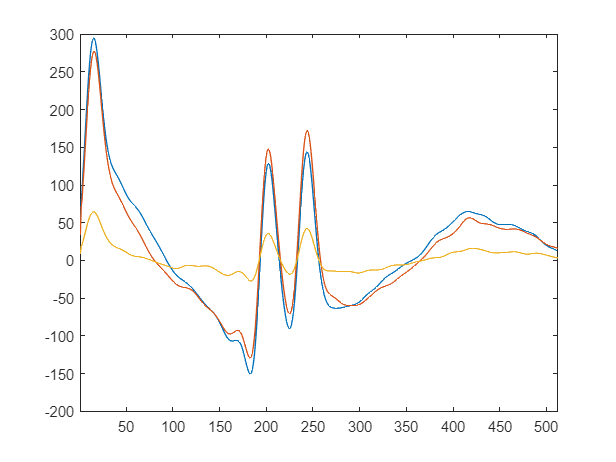

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

figure;i = 1;
plot(XTrain{i}');
xlim([1 size(XTrain{i},2)]);

## Hyper-parameter search

|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | miniBatchSize| learningrate | numLSTMBlocks| numHiddenUni-| numCNNBlocks |   filterSize |   numFilters |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | ts           |              |              |              |
|================================================================================================================================================================================|
|    1 | Best   |     0.12247 |      1376.2 |     0.12247 |     0.12247 |           18 |     0.019455 |            4 |          176 |            3 |           32 |            4 |


|    2 | Accept |           1 |      67.338 |     0.12247 |     0.12247 |           44 |     0.072551 |            2 |           90 |            2 |            6 |            7 |
|    3 | Accept |     0.12247 |      384.52 |     0.12247 |     0.12247 |           63 |     0.035028 |            5 |           49 |            4 |           12 |            5 |
|    4 | Best   |    0.084724 |      1083.7 |    0.084724 |    0.084724 |            9 |   0.00022018 |            2 |          147 |            4 |            3 |            3 |
|    5 | Best   |    0.080194 |      897.76 |    0.080194 |    0.080195 |           12 |   0.00056024 |            2 |          196 |            4 |            3 |            3 |
|    6 | Best   |    0.077402 |      354.98 |    0.077402 |    0.077402 |           64 |     0.016306 |            5 |           42 |            2 |            9 |            1 |
|    7 | Accept |    0.091043 |      217.21 |    0.077402 |    0.077402 |           62 |     0.066704 |  

|    9 | Accept |           1 |      1048.1 |    0.077402 |    0.077402 |           44 |      0.05559 |            4 |          226 |            3 |            4 |            2 |
|   10 | Best   |    0.076068 |      684.25 |    0.076068 |    0.076068 |           43 |   0.00053752 |            5 |           92 |            3 |           27 |            8 |
|   11 | Accept |    0.079968 |       250.2 |    0.076068 |    0.076068 |           44 |     0.054461 |            2 |           12 |            1 |            6 |            6 |
|   12 | Accept |    0.077321 |      448.38 |    0.076068 |    0.076068 |           44 |     0.028743 |            2 |          133 |            3 |           31 |            6 |
|   13 | Accept |     0.10331 |      277.53 |    0.076068 |    0.076068 |           44 |   0.00014633 |            2 |           86 |            1 |            3 |            1 |
|   14 | Accept |    0.084909 |      364.54 |    0.076068 |    0.076068 |           44 |     0.019126 |  

|   15 | Accept |           1 |      309.11 |    0.076068 |    0.076068 |           10 |     0.054255 |            2 |           70 |            2 |           23 |            3 |
|   16 | Accept |     0.08787 |      171.24 |    0.076068 |    0.076068 |           57 |     0.064489 |            1 |           86 |            2 |            5 |            4 |


|   17 | Accept |           1 |       126.3 |    0.076068 |    0.076068 |           48 |     0.090723 |            2 |           83 |            2 |            4 |            2 |


|   18 | Accept |           1 |      109.02 |    0.076068 |    0.076068 |           47 |     0.098752 |            2 |           81 |            3 |            2 |            5 |
|   19 | Accept |    0.081048 |      373.81 |    0.076068 |    0.076068 |           49 |      0.03638 |            3 |           69 |            2 |            6 |            8 |
|   20 | Accept |    0.083737 |      169.16 |    0.076068 |    0.076068 |           52 |      0.05086 |            1 |           59 |            1 |            4 |            7 |
|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | miniBatchSize| learningrate | numLSTMBlocks| numHiddenUni-| numCNNBlocks |   filterSize |   numFilters |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |  

|   28 | Accept |           1 |      96.542 |    0.076068 |    0.076068 |           64 |     0.080632 |            1 |           97 |            4 |            6 |            2 |
|   29 | Accept |    0.086064 |      309.81 |    0.076068 |    0.076068 |           43 |     0.014809 |            2 |           87 |            1 |           10 |            7 |
|   30 | Accept |    0.084431 |      162.52 |    0.076068 |    0.076068 |           61 |     0.019034 |            1 |           65 |            2 |            5 |            6 |
|   31 | Accept |    0.080982 |      236.05 |    0.076068 |    0.076068 |           62 |     0.027425 |            2 |           63 |            4 |            1 |            1 |
|   32 | Accept |    0.081184 |      146.93 |    0.076068 |    0.076068 |           62 |   0.00055671 |            1 |           59 |            1 |            9 |            8 |
|   33 | Accept |    0.080386 |      230.82 |    0.076068 |    0.076068 |           58 |   0.00041114 |  

|   35 | Accept |           1 |      125.74 |    0.076068 |    0.076068 |           41 |     0.054537 |            1 |          128 |            3 |            5 |            5 |
|   36 | Accept |    0.081614 |      1110.1 |    0.076068 |    0.076068 |           11 |    0.0066121 |            2 |           63 |            2 |            4 |            6 |
|   37 | Accept |    0.078674 |      167.72 |    0.076068 |    0.076068 |           61 |   0.00031775 |            1 |           27 |            3 |            1 |            4 |
|   38 | Accept |    0.076513 |      164.48 |    0.076068 |    0.076068 |           60 |   0.00029897 |            1 |           45 |            2 |           11 |            3 |
|   39 | Accept |    0.080562 |      318.79 |    0.076068 |    0.076068 |           44 |   0.00025153 |            2 |           71 |            2 |            4 |            6 |
|   40 | Accept |    0.082802 |      170.71 |    0.076068 |    0.076068 |           64 |    0.0012909 |  

|   44 | Accept |           1 |      47.897 |    0.076068 |    0.076068 |           45 |     0.082354 |            1 |          105 |            1 |           15 |            2 |
|   45 | Accept |    0.098668 |      196.37 |    0.076068 |    0.076068 |           61 |     0.059381 |            1 |           21 |            4 |           28 |            2 |
|   46 | Accept |     0.12247 |      243.44 |    0.076068 |    0.076068 |           63 |     0.057349 |            1 |          120 |            4 |           20 |            7 |
|   47 | Accept |    0.093528 |      161.28 |    0.076068 |    0.076068 |           63 |    0.0094848 |            1 |           37 |            2 |            8 |            7 |
|   48 | Accept |    0.080683 |      212.61 |    0.076068 |    0.076068 |           58 |   0.00081565 |            1 |           47 |            4 |            4 |            6 |
|   49 | Accept |    0.086723 |      160.27 |    0.076068 |    0.076068 |           63 |    0.0037197 |  

|   64 | Accept |           1 |      82.755 |    0.076068 |    0.076068 |           59 |     0.058847 |            1 |          102 |            1 |            6 |            5 |
|   65 | Accept |    0.078948 |      182.35 |    0.076068 |    0.076068 |           54 |   0.00052682 |            1 |           15 |            2 |            7 |            5 |
|   66 | Accept |    0.087589 |       258.5 |    0.076068 |    0.076068 |           63 |     0.051074 |            2 |           34 |            5 |           11 |            7 |


|   67 | Accept |           1 |      269.82 |    0.076068 |    0.076068 |           58 |     0.048764 |            2 |           99 |            3 |           30 |            5 |
|   68 | Accept |    0.087215 |       181.1 |    0.076068 |    0.076068 |           47 |     0.046438 |            1 |           52 |            1 |           28 |            7 |
|   69 | Accept |    0.077483 |      153.95 |    0.076068 |    0.076068 |           63 |   0.00086615 |            1 |           33 |            2 |            3 |            2 |
|   70 | Accept |    0.077485 |      167.85 |    0.076068 |    0.076068 |           63 |     0.050865 |            1 |           87 |            2 |           10 |            7 |


|   71 | Accept |           1 |      75.308 |    0.076068 |    0.076068 |           45 |     0.089154 |            1 |           75 |            3 |           30 |            3 |
|   72 | Accept |     0.11151 |      175.19 |    0.076068 |    0.076068 |           64 |   0.00017368 |            1 |            4 |            2 |           20 |            1 |


|   73 | Accept |           1 |       93.64 |    0.076068 |    0.076068 |           25 |     0.084066 |            1 |          119 |            5 |            5 |            4 |


|   74 | Accept |           1 |      140.27 |    0.076068 |    0.076068 |           58 |     0.080478 |            1 |           61 |            5 |           30 |            8 |
|   75 | Accept |    0.086181 |      176.09 |    0.076068 |    0.076068 |           50 |     0.013668 |            1 |           57 |            1 |            1 |            8 |


|   76 | Accept |           1 |      62.239 |    0.076068 |    0.076068 |           45 |     0.096187 |            1 |           60 |            1 |           16 |            8 |


|   77 | Accept |           1 |      118.66 |    0.076068 |    0.076068 |           54 |      0.09183 |            2 |           99 |            2 |            7 |            2 |
|   78 | Accept |    0.084653 |       170.9 |    0.076068 |    0.076068 |           62 |     0.055244 |            1 |            4 |            2 |           17 |            3 |
|   79 | Accept |     0.07986 |      176.56 |    0.076068 |    0.076068 |           59 |     0.031761 |            1 |          102 |            1 |            9 |            7 |
|   80 | Accept |    0.082287 |      176.66 |    0.076068 |    0.076068 |           63 |       0.0067 |            1 |           28 |            4 |            7 |            5 |
|================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | miniBatchSize| learningrate | n

|   86 | Accept |           1 |      36.998 |    0.074819 |    0.074819 |           49 |     0.094794 |            1 |           93 |            2 |           29 |            6 |
|   87 | Accept |    0.088601 |      171.57 |    0.074819 |    0.074819 |           61 |     0.054327 |            1 |           61 |            2 |           28 |            3 |
|   88 | Accept |    0.082472 |      153.07 |    0.074819 |    0.074819 |           60 |    0.0028811 |            1 |           52 |            1 |           13 |            4 |
|   89 | Accept |    0.079214 |       142.2 |    0.074819 |    0.074819 |           62 |   0.00058357 |            1 |           15 |            1 |           13 |            3 |
|   90 | Accept |    0.075231 |      193.07 |    0.074819 |    0.074819 |           54 |     0.046665 |            1 |          101 |            1 |           15 |            2 |
|   91 | Accept |      0.0766 |      147.07 |    0.074819 |    0.074819 |           60 |   0.00041318 |  

|  100 | Accept |           1 |      183.26 |    0.074819 |    0.074819 |           62 |     0.059978 |            1 |          128 |            5 |            7 |            3 |


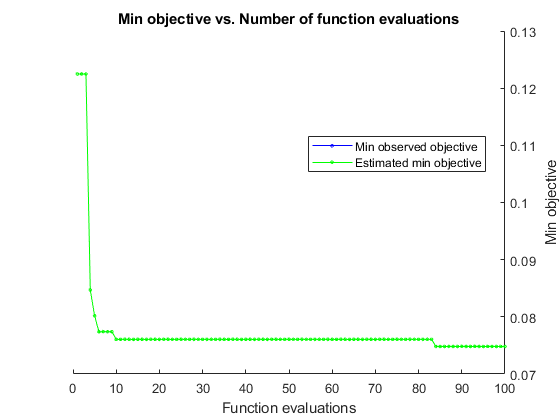


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 100 reached.
Total function evaluations: 100
Total elapsed time: 24992.5828 seconds
Total objective function evaluation time: 24940.8381

Best observed feasible point:
    miniBatchSize    learningrate    numLSTMBlocks    numHiddenUnits    numCNNBlocks    filterSize    numFilters
    _____________    ____________    _____________    ______________    ____________    __________    __________

         63           0.0068721            1                8                5              27            2     

Observed objective function value = 0.074819
Estimated objective function value = 0.074819
Function evaluation time = 222.6491

Best estimated

maxEpochs = 30;
optimVars = [%numLSTMBlocks,numHiddenUnits,numCNNBlocks,filterSize,numFilters    
    optimizableVariable('miniBatchSize',[8 128],'Type','integer')                   %[8 128]
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")
    optimizableVariable('numLSTMBlocks',[1 6],'Type','integer')                     %[1 5]
    optimizableVariable('numHiddenUnits',[1 256],'Type','integer')
    optimizableVariable('numCNNBlocks',[1 6],'Type','integer')                      %[1 5]
    optimizableVariable('filterSize',[1 32],'Type','integer')
    optimizableVariable('numFilters',[1 8],'Type','integer')];

objectFunction = objectFunctionLSTMCNN(trainDs, testDs,  maxEpochs);
    
% optimizer
BayesObject = bayesopt( objectFunction,             optimVars, ...
                        'MaxTime',                  24*60*60, ...
                        'Verbose',                  1,...
                        "UseParallel",              false,...
                        'IsObjectiveDeterministic', true, ...
                        'ParallelMethod',           "clipped-model-prediction",...
                        'MaxObjectiveEvaluations',  100,...
                        'ExplorationRatio',         0.6,...
                        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);

mkdir('HyperParameterSearch\OptVars');

save("HyperParameterSearch\OptVars\LSTMCNNoptVars.mat","optVars","-mat");


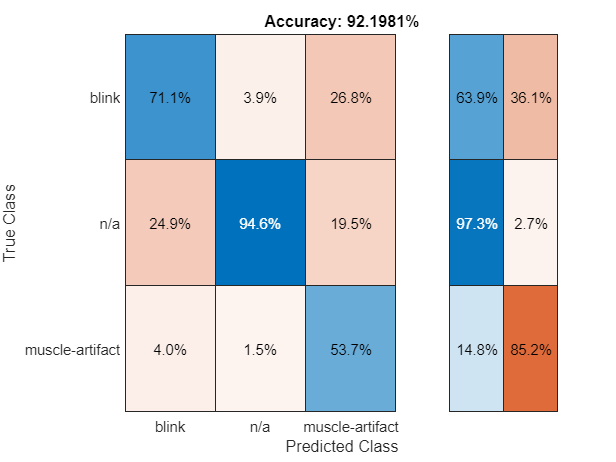

    % Evaluate and train the network with the optimal parameters
[valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end
percentageAccuracy=(1-valError)*100;
figure;
confusionchart(TY(:),Y(:),'Normalization','column-normalized','Title',['Accuracy: ' num2str(percentageAccuracy) '%'], ...
   'RowSummary','row-normalized');